clc;
clear all;
close all;

Init

% % number of tx and rx antennas
numTx = [2,4,8,16,32,64,128];
numRx = [2,4,8,16,32,64,128];

% number of scenarios
scenario_num = length(numTx);

% modulation order (16-QAM)
M = 16;

% number of transmitted symbols (the larger the more precise the results will be)
% num_symbols = 36864*numTx;
num_symbols = 65536*numTx;

% points to plot
% points = 20;
points = 10;
% Min and Max Eb/N0
eb_n0_min = 8;
eb_n0_max = 18;
% generates an array of Eb/N0 values in the range [eb_n0_min, eb_n0_max] with a length equal to points
eb_n0 = linspace(eb_n0_min,eb_n0_max,points);

% % min and max value for snr
% snr_min = 15;
% snr_max = 35;
% % generates an array of SNR values in the range [snr_min, snr_max] with a length equal to points
% snr=linspace(snr_min,snr_max,points);
% 
% % Energy per symbol
% Es = sum(abs(symbols).^2) / length(symbols);
% % Energy per bit
% Eb = Es / log2(M);
% % Convert SNR to Eb/N0
% eb_n0 = snr - 10 * log10(Eb);
% % Min and Max Eb/N0
% eb_n0_min = min(eb_n0);
% eb_n0_max = max(eb_n0);

% Initialize Bit Error Rate vector for ZF and V-BLAST
ber_zf = zeros(scenario_num, points);
ber_vblast = zeros(scenario_num, points);

Scenario 1 : 2x2 Tx-Rx

% simulation index
index_sim = 1;

% Compute the ber
[ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

vblast Elapsed time is 20.591272 seconds.
zf Elapsed time is 0.977878 seconds.
vblast Elapsed time is 20.191181 seconds.
zf Elapsed time is 0.931794 seconds.
vblast Elapsed time is 20.036981 seconds.
zf Elapsed time is 0.931540 seconds.
vblast Elapsed time is 20.069939 seconds.
zf Elapsed time is 0.927184 seconds.
vblast Elapsed time is 20.142302 seconds.
zf Elapsed time is 0.953861 seconds.
vblast Elapsed time is 20.026217 seconds.
zf Elapsed time is 0.967939 seconds.
vblast Elapsed time is 20.114665 seconds.
zf Elapsed time is 0.947201 seconds.
vblast Elapsed time is 19.954075 seconds.
zf Elapsed time is 1.016613 seconds.
vblast Elapsed time is 19.398616 seconds.
zf Elapsed time is 0.953524 seconds.
vblast Elapsed time is 19.891410 seconds.
zf Elapsed time is 0.897508 seconds.


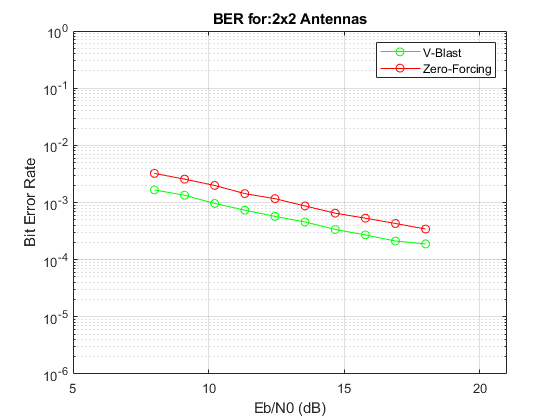


% plot the results
semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
hold on;
semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^-1])
title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 2: 4x4 Tx-Rx

% simulation index
index_sim = 2;

% Compute the ber
[ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

vblast Elapsed time is 41.159185 seconds.
zf Elapsed time is 1.161296 seconds.
vblast Elapsed time is 40.130921 seconds.
zf Elapsed time is 1.158125 seconds.
vblast Elapsed time is 41.191108 seconds.
zf Elapsed time is 1.282533 seconds.
vblast Elapsed time is 42.154349 seconds.
zf Elapsed time is 1.200391 seconds.
vblast Elapsed time is 41.863004 seconds.
zf Elapsed time is 1.208280 seconds.
vblast Elapsed time is 41.856551 seconds.
zf Elapsed time is 1.199769 seconds.
vblast Elapsed time is 40.828691 seconds.
zf Elapsed time is 1.184528 seconds.
vblast Elapsed time is 44.050298 seconds.
zf Elapsed time is 1.235795 seconds.
vblast Elapsed time is 50.445523 seconds.
zf Elapsed time is 1.259155 seconds.
vblast Elapsed time is 45.832575 seconds.
zf Elapsed time is 1.297613 seconds.


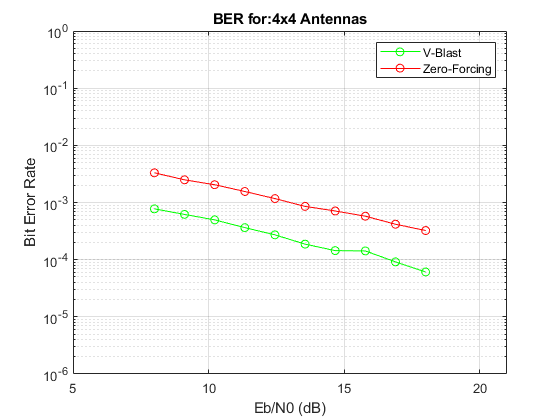



% plot the results
semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
hold on;
semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^-1])
title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 3: 8x8 Tx-Rx

% simulation index
index_sim = 3;

% Compute the ber

[ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

vblast Elapsed time is 94.233975 seconds.
zf Elapsed time is 2.021999 seconds.
vblast Elapsed time is 91.463110 seconds.
zf Elapsed time is 2.243817 seconds.
vblast Elapsed time is 93.769693 seconds.
zf Elapsed time is 2.054392 seconds.
vblast Elapsed time is 92.730844 seconds.
zf Elapsed time is 2.163523 seconds.
vblast Elapsed time is 95.324346 seconds.
zf Elapsed time is 2.066374 seconds.
vblast Elapsed time is 94.142341 seconds.
zf Elapsed time is 2.014607 seconds.
vblast Elapsed time is 97.817848 seconds.
zf Elapsed time is 1.981858 seconds.
vblast Elapsed time is 98.111112 seconds.
zf Elapsed time is 2.033403 seconds.
vblast Elapsed time is 93.056780 seconds.
zf Elapsed time is 1.988961 seconds.
vblast Elapsed time is 89.628777 seconds.
zf Elapsed time is 2.076546 seconds.


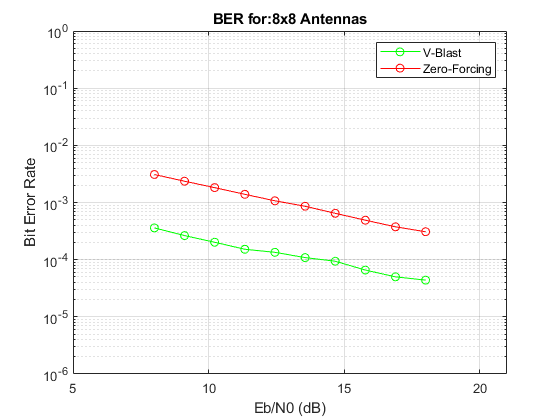


% plot the results
semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
hold on;
semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^-1])
title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 4: 16x16 Tx-Rx

% simulation index
index_sim = 4;

% Compute the ber
[ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

vblast Elapsed time is 277.562066 seconds.
zf Elapsed time is 5.304818 seconds.
vblast Elapsed time is 278.489555 seconds.
zf Elapsed time is 5.355594 seconds.
vblast Elapsed time is 280.346774 seconds.
zf Elapsed time is 5.387017 seconds.
vblast Elapsed time is 279.901116 seconds.
zf Elapsed time is 5.349300 seconds.
vblast Elapsed time is 280.482350 seconds.
zf Elapsed time is 5.318301 seconds.
vblast Elapsed time is 281.306190 seconds.
zf Elapsed time is 5.308741 seconds.
vblast Elapsed time is 275.320978 seconds.
zf Elapsed time is 5.321977 seconds.
vblast Elapsed time is 276.303213 seconds.
zf Elapsed time is 5.660816 seconds.
vblast Elapsed time is 277.214867 seconds.
zf Elapsed time is 5.534570 seconds.
vblast Elapsed time is 277.771206 seconds.
zf Elapsed time is 5.312267 seconds.


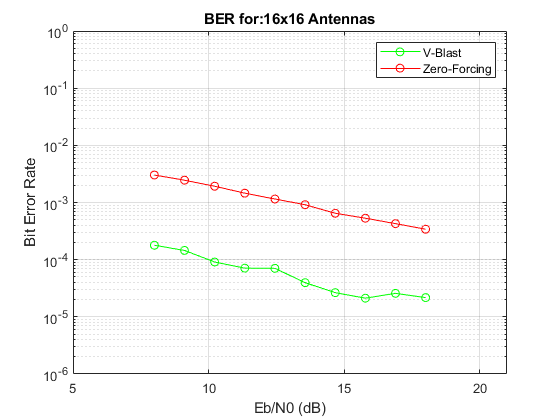


% plot the results
semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
hold on;
semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^-1])
title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 5: 32x32 Tx-Rx

% simulation index
index_sim = 5;

% Compute the ber
[ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

vblast Elapsed time is 1178.574003 seconds.
zf Elapsed time is 25.662203 seconds.
vblast Elapsed time is 1181.251308 seconds.
zf Elapsed time is 25.689388 seconds.
vblast Elapsed time is 1181.256279 seconds.
zf Elapsed time is 25.636114 seconds.
vblast Elapsed time is 1181.640130 seconds.
zf Elapsed time is 25.864520 seconds.
vblast Elapsed time is 1181.801654 seconds.
zf Elapsed time is 25.787860 seconds.
vblast Elapsed time is 1184.389916 seconds.
zf Elapsed time is 25.557793 seconds.
vblast Elapsed time is 1182.917856 seconds.
zf Elapsed time is 25.686446 seconds.
vblast Elapsed time is 1182.416667 seconds.
zf Elapsed time is 25.636762 seconds.
vblast Elapsed time is 1182.534632 seconds.
zf Elapsed time is 25.696101 seconds.
vblast Elapsed time is 1183.226685 seconds.
zf Elapsed time is 25.441609 seconds.


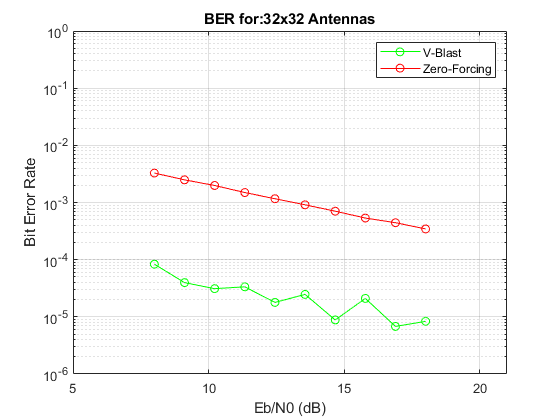


% plot the results
semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
hold on;
semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^-1])
title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 6: 64x64 Tx-Rx

% simulation index
index_sim = 6;

% Compute the ber
[ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

vblast Elapsed time is 4070.099443 seconds.
zf Elapsed time is 64.352078 seconds.
vblast Elapsed time is 4097.821443 seconds.
zf Elapsed time is 62.377879 seconds.
vblast Elapsed time is 4095.537522 seconds.
zf Elapsed time is 62.427299 seconds.
vblast Elapsed time is 4097.457003 seconds.
zf Elapsed time is 62.803668 seconds.
vblast Elapsed time is 4112.088638 seconds.
zf Elapsed time is 62.405949 seconds.
vblast Elapsed time is 4105.403521 seconds.
zf Elapsed time is 62.651409 seconds.
vblast Elapsed time is 4096.067385 seconds.
zf Elapsed time is 62.906201 seconds.
vblast Elapsed time is 4091.949679 seconds.
zf Elapsed time is 62.457032 seconds.
vblast Elapsed time is 4223.309766 seconds.
zf Elapsed time is 86.422397 seconds.
vblast Elapsed time is 4341.325801 seconds.
zf Elapsed time is 81.491561 seconds.


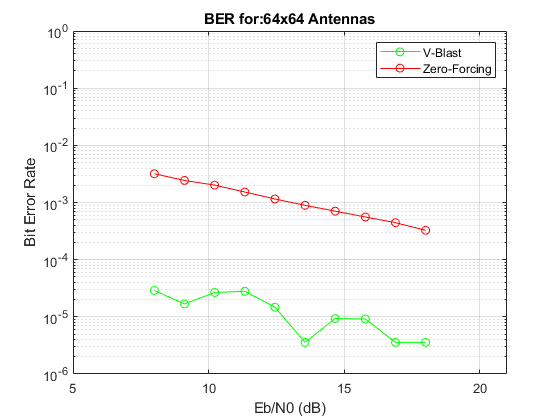


% plot the results
semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
hold on;
semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
hold off
xlim([eb_n0_min-3, eb_n0_max+3])
ylim([10^-6, 10^-1])
title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
legend('V-Blast','Zero-Forcing');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Scenario 7: 128x128 Tx-Rx

% % simulation index
% index_sim = 7;
% 
% % Compute the ber
% [ber_zf(index_sim,:), ber_vblast(index_sim,:)] = com_sys(numTx(index_sim), numRx(index_sim), num_symbols(index_sim), M, eb_n0);

Requested 1x128x128x65536 (16.0GB) array exceeds maximum array size preference. Creation of arrays greater than this limit may take a long time and cause MATLAB to become unresponsive.

Error in kron (line 35)
   K = reshape(A.*B, ma*mb, na*nb);

Error in com_sys (line 22)
xmod=kron(xmod,deltas);

Related documentation

% 
% % plot the results
% semilogy(eb_n0,ber_vblast(index_sim,:),'g-o');
% hold on;
% semilogy(eb_n0,ber_zf(index_sim,:),'r-o');
% hold off
% xlim([eb_n0_min-3, eb_n0_max+3])
% ylim([10^-6, 10^-1])
% title({ strcat('BER for: ', num2str(numTx(index_sim)), 'x' , num2str(numRx(index_sim)), ' Antennas')})
% legend('V-Blast','Zero-Forcing');
% xlabel('Eb/N0 (dB)');
% ylabel('Bit Error Rate');
% grid on